# Init Global params

clear
prefix = '0317';
bmp_path = './BMP/';
pixelSize = 0.6; % in um
levels = 256;

xCellSize = 50; % in um
yCellSize = 50; % in um
xSepSize = 50; % in um
ySepSize = 50; % in um

pattern_cells = {};

incident_angle = 0;
target_angle = 20;
Target = 1;
Wavelength=1.55;
Period = abs(Target)*Wavelength./abs(sind(target_angle)-sind(incident_angle));
disp(['Beginning Period: ' sprintf('%.2f um; ',Period)])

Beginning Period: 4.53 um; 


ang = asind(abs(Target)*Wavelength./(ceil(Period/pixelSize)*pixelSize) + sind(incident_angle));
disp(['Upper angle: ' sprintf('%.2f deg; ',ang)])

Upper angle: 18.84 deg; 


ang = asind(abs(Target)*Wavelength./(floor(Period/pixelSize)*pixelSize) + sind(incident_angle));
disp(['Lower angle: ' sprintf('%.2f deg; ',ang)])

Lower angle: 21.66 deg; 


ang = asind(abs(Target)*Wavelength./(round(Period/pixelSize)*pixelSize) + sind(incident_angle));
disp(['[Center angle]: ' sprintf('%.2f deg; ',ang)])

[Center angle]: 18.84 deg; 


Period = round(Period/pixelSize)*pixelSize;
disp(['[Period]: ' sprintf('%.2f um; ',Period)])

[Period]: 4.80 um; 


## Gen sampling pattern

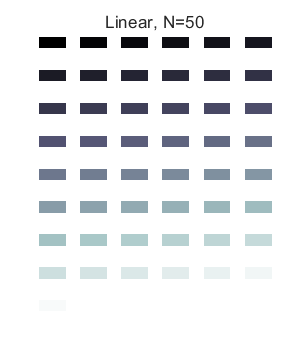

% each row contains period_list*offset_list cells
N = 50;
level_list = uint8(linspace(0,levels-1,N)); % in um

xCellSize = 40; % in um
yCellSize = 50; % in um

figure('Position',[0 0 300 350])
t=tiledlayout('flow','TileSpacing',"compact");
title(t,['Linear, N=',num2str(N)])
Ny = round(yCellSize/pixelSize);
for ii = 1:length(level_list)
    % horizontal arrangement
    Nx = ceil(xCellSize/pixelSize);
    I = repmat(level_list(ii),1,Nx);
    I = repmat(I,Ny,1);
    pattern_cells = [pattern_cells,I];
    nexttile
    imagesc([0 pixelSize*size(I,2)],[0 pixelSize*size(I,1)],I);
    colormap(bone)
    axis off
    caxis([0 255])
end

disp(level_list)

  列 1 至 24

     0     5    10    16    21    26    31    36    42    47    52    57    62    68    73    78    83    88    94    99   104   109   114   120

  列 25 至 48

   125   130   135   141   146   151   156   161   167   172   177   182   187   193   198   203   208   213   219   224   229   234   239   245

  列 49 至 50

   250   255



suffix = '-samp';

## Gen bar pattern

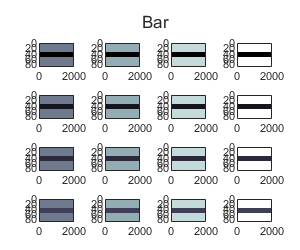

% each row contains period_list*offset_list cells
width = 9; % in um
period = 90; % in um
D_line = round(linspace(0,72,4));
D_bg = round(linspace(128,255,4));

Nx = 1; % number of period
yCellSize = 2000; % in um
Ny = round(yCellSize/pixelSize);

figure('Position',[0 0 300 250])
t=tiledlayout('flow','TileSpacing',"compact");
title(t,'Bar')
for ii = 1:length(D_line)
    for jj = 1:length(D_bg)
        % bar pattern
        tmp = zeros(1,round(period/pixelSize));
        line_ind = abs((1:length(tmp))-round(length(tmp)/2))<=round(width/pixelSize);
        tmp(line_ind) = D_line(ii);
        tmp(~line_ind) = D_bg(jj);
        tmp = uint8(tmp);
        tmp = repmat(tmp,1,Nx);
        I = repmat(tmp,Ny,1)';
        pattern_cells = [pattern_cells,I];
        nexttile
        imagesc([0 pixelSize*size(I,2)],[0 pixelSize*size(I,1)],I);
        caxis([0,levels])
        colormap(bone)
    end
end

suffix = '-bar';


# Merge Pattern Cells along y

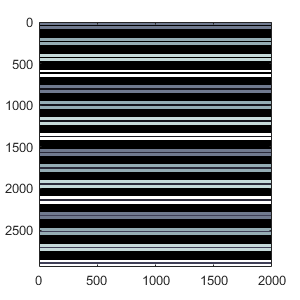

suffix = '-merged';
try
    delete([bmp_path,prefix,suffix,'.bmp'])
end
xSepSize = 0;
ySepSize = 100;
pattern_cells;
I_tot = MergeCells('y',xSepSize,ySepSize,pixelSize,pattern_cells);

imwrite(I_tot, [bmp_path,prefix,suffix,'.bmp']);
figure('Position',[0 0 300 300])
imagesc([0 pixelSize*size(I_tot,2)],[0 pixelSize*size(I_tot,1)],I_tot);
colormap(bone)

disp( [bmp_path,prefix,suffix,'.bmp'])

./BMP/0317-merged.bmp


disp(['Size: ' sprintf('%.1f',size(I_tot,2)*pixelSize),' x ',sprintf('%.1f',size(I_tot,1)*pixelSize), ' um'])

Size: 1999.8 x 2943.0 um



disp(['Eff area: ' num2str(sum(I_tot>0,"all")*pixelSize^2/1e6) ' mm^2'])

Eff area: 2.7309 mm^2


disp(['Expose Time per N-over: ' num2str(40/60*sum(I_tot>0,"all")*pixelSize^2/1e6) ' min'])

Expose Time per N-over: 1.8206 min


# Merge Pattern Cells with arrangement

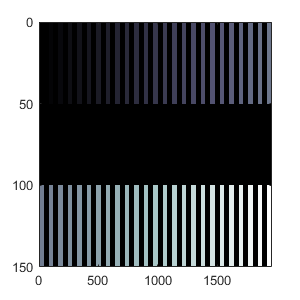

suffix = '-merged';
try
    delete([bmp_path,prefix,suffix,'.bmp'])
end
xSepSize = 40;
ySepSize = 50;
pattern_cells;
rows = [25,25];
I_tot = MergeCells(rows,xSepSize,ySepSize,pixelSize,pattern_cells);

imwrite(I_tot, [bmp_path,prefix,suffix,'.bmp']);
figure('Position',[0 0 300 300])
imagesc([0 pixelSize*size(I_tot,2)],[0 pixelSize*size(I_tot,1)],I_tot);
colormap(bone)

disp( [bmp_path,prefix,suffix,'.bmp'])

./BMP/0201-merged.bmp


disp(['Size: ' sprintf('%.1f',size(I_tot,2)*pixelSize),' x ',sprintf('%.1f',size(I_tot,1)*pixelSize), ' um'])

Size: 1960.0 x 150.0 um


disp(['Eff area: ' num2str(sum(I_tot>0,"all")*pixelSize^2/1e6) ' mm^2'])

Eff area: 0.098 mm^2


disp(['Expose Time per N-over: ' num2str(40/60*sum(I_tot>0,"all")*pixelSize^2/1e6) ' min'])

Expose Time per N-over: 0.065333 min


# Merge BMPs 

suffix = '-merged';
try
    delete([bmp_path,prefix,suffix,'.bmp'])
end

BmpCells = LoadBmpList(bmp_path,prefix);
xSepSize = 30;
ySepSize = 30;
I_tot = MergeCells('y',xSepSize,ySepSize,pixelSize,BmpCells);

imwrite(I_tot, [bmp_path,prefix,suffix,'.bmp']);
imshow(I_tot)
disp( [bmp_path,prefix,suffix,'.bmp'])
disp(['Size: ' sprintf('%.1f',size(I_tot,2)*pixelSize),' x ',sprintf('%.1f',size(I_tot,1)*pixelSize), ' um'])

function BmpCells = LoadBmpList(bmp_path,prefix)
bmp_list = ls([bmp_path,prefix,'*.bmp']);
BmpCells = cell(1,size(bmp_list,1));
for kk = 1:size(bmp_list,1)
    % load file
    BmpCells{kk} = imread([bmp_path,bmp_list(kk,:)]);
end
end

function I_tot = MergeCells(layout,xSepSize,ySepSize,pixelSize,pattern_cells)
if isnumeric(layout)
    if length(layout)==2
        if layout(1)==1
            layout = 'x';
        elseif layout(2)==1
            layout = 'y';
        end
    end
end
% 沿x排列
if strcmp(layout,'x')
    for kk = 1:length(pattern_cells)
        % load pattern
        I = pattern_cells{kk};
        % horizontal stacking
        if kk==1
            I_tot = I;
        else
            if size(I,1)>size(I_tot,1)
                I_tot = [[I_tot;zeros(size(I,1)-size(I_tot,1),size(I_tot,2))],...
                    zeros(size(I,1),round(xSepSize/pixelSize)), I];
            else
                I_tot = [I_tot,...
                    zeros(size(I_tot,1),round(xSepSize/pixelSize)),...
                    [I;zeros(size(I_tot,1)-size(I,1),size(I,2))]];
            end
        end
    end
% 沿y排列
elseif strcmp(layout,'y')
    for kk = 1:length(pattern_cells)
        % load file
        I = pattern_cells{kk};
        % vertical stacking
        if kk==1
            I_tot = I;
        else
            if size(I,2)>size(I_tot,2)
                I_tot = [I_tot,zeros(size(I_tot,1),size(I,2)-size(I_tot,2));...
                    zeros(round(ySepSize/pixelSize),size(I,2)); I];
            else
                I_tot = [I_tot;...
                    zeros(round(ySepSize/pixelSize),size(I_tot,2));...
                    I,zeros(size(I,1),size(I_tot,2)-size(I,2))];
            end
        end
    end
else
    % 沿Nx列 Ny行排列
    if length(layout)==2
        Nx = layout(1);
        Ny = layout(2);
        for kk = 1:length(pattern_cells)
            % load file
            I = pattern_cells{kk};
            xind = mod(kk,Nx);
            yind = ceil(kk/Nx);
            if xind==1
                I_horizon = I;
            else
                % horizontal stacking
                if size(I,1)>size(I_horizon,1)
                    I_horizon = [[I_horizon;zeros(size(I,1)-size(I_horizon,1),size(I_horizon,2))],...
                        zeros(size(I,1),round(xSepSize/pixelSize)), I];
                else
                    I_horizon = [I_horizon,...
                        zeros(size(I_horizon,1),round(xSepSize/pixelSize)),...
                        [I;zeros(size(I_horizon,1)-size(I,1),size(I,2))]];
                end
            end
            % 一行排满
            if xind==0 || kk==length(pattern_cells)
                % vertical stacking
                if yind==1
                    I_tot = I_horizon;
                else
                    if size(I_horizon,2)>size(I_tot,2)
                        I_tot = [I_tot,zeros(size(I_tot,1),size(I_horizon,2)-size(I_tot,2));...
                            zeros(round(ySepSize/pixelSize),size(I_horizon,2)); I_horizon];
                    else
                        I_tot = [I_tot;...
                            zeros(round(ySepSize/pixelSize),size(I_tot,2));...
                            I_horizon,zeros(size(I_horizon,1),size(I_tot,2)-size(I_horizon,2))];
                    end
                end
            end
        end
    else
        % 沿列数矩阵规定的列数依次排列各行
        ind = 1;
        if_first_row = 1;
        for kk = 1:length(pattern_cells)
            % load file
            I = pattern_cells{kk};
            Nx = layout(ind);
            xind = mod(kk-sum(layout(1:ind-1)),Nx);
            if xind==1 || Nx==1
                I_horizon = I;
            else
                % horizontal stacking
                if size(I,1)>size(I_horizon,1)
                    I_horizon = [[I_horizon;zeros(size(I,1)-size(I_horizon,1),size(I_horizon,2))],...
                        zeros(size(I,1),round(xSepSize/pixelSize)), I];
                else
                    I_horizon = [I_horizon,...
                        zeros(size(I_horizon,1),round(xSepSize/pixelSize)),...
                        [I;zeros(size(I_horizon,1)-size(I,1),size(I,2))]];
                end
            end
            % 一行排满
            if xind==0 || kk==length(pattern_cells)
                ind = ind+1;
                % vertical stacking
                if if_first_row==1
                    I_tot = I_horizon;
                    if_first_row = 0;
                else
                    if size(I_horizon,2)>size(I_tot,2)
                        I_tot = [I_tot,zeros(size(I_tot,1),size(I_horizon,2)-size(I_tot,2));...
                            zeros(round(ySepSize/pixelSize),size(I_horizon,2)); I_horizon];
                    else
                        I_tot = [I_tot;...
                            zeros(round(ySepSize/pixelSize),size(I_tot,2));...
                            I_horizon,zeros(size(I_horizon,1),size(I_tot,2)-size(I_horizon,2))];
                    end
                end
            end
        end
    end
end
end